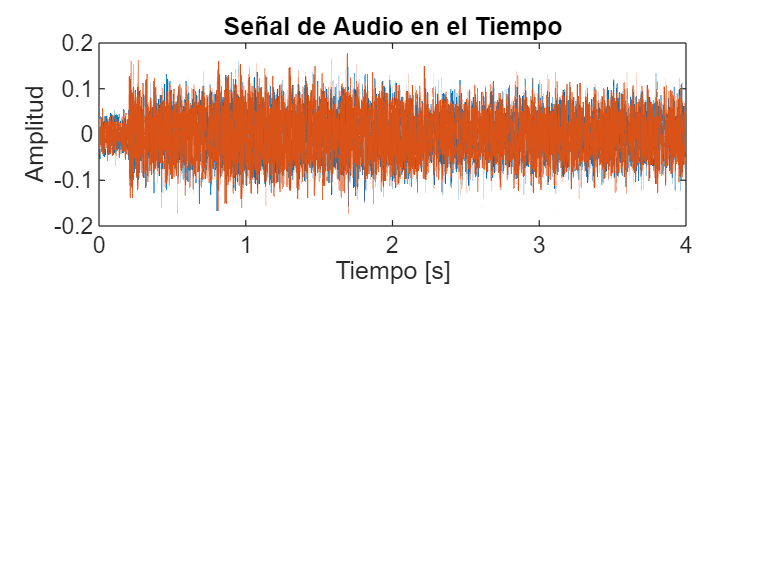

[x, Fs] = audioread('construccion1.wav');

N = length(x);  % Número de muestras
t = (0:N-1)/Fs;  % Vector de tiempo para graficar la señal en segundos

%audio = audio;
sound(x, Fs);
% Figura para la señal en el tiempo
figure;
subplot(2,1,1); 
plot(t, x);
title('Señal de Audio en el Tiempo');
xlabel('Tiempo [s]');
ylabel('Amplitud');

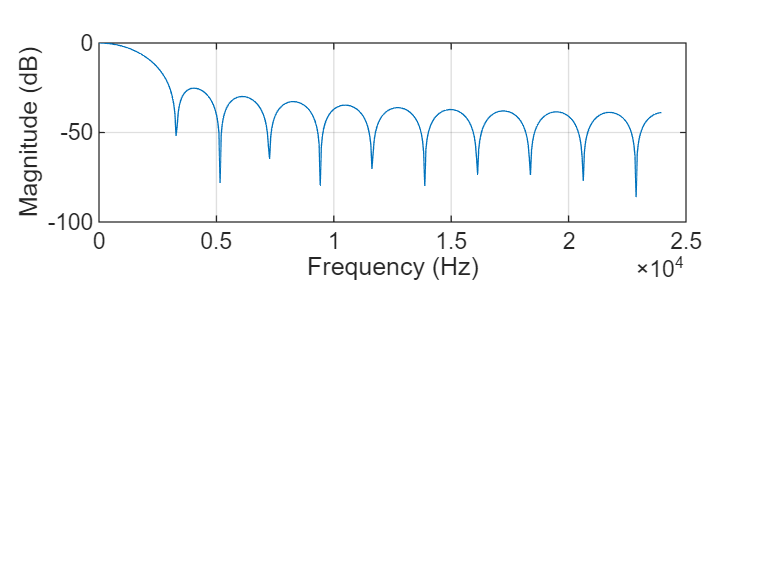

fc = 120;
Wn = (2/Fs)*fc;
b = fir1(20,Wn,'low',kaiser(21,3));

[h,f] = freqz(b,1,[],Fs);
plot(f,mag2db(abs(h)))
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
grid

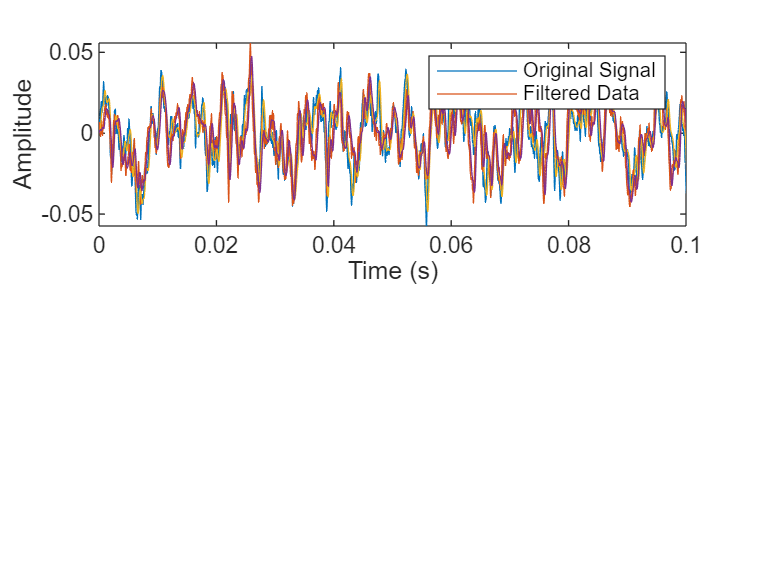

y = filter(b,1,x);

plot(t,x,t,y)
xlim([0 0.1])

xlabel('Time (s)')
ylabel('Amplitude')
legend('Original Signal','Filtered Data')

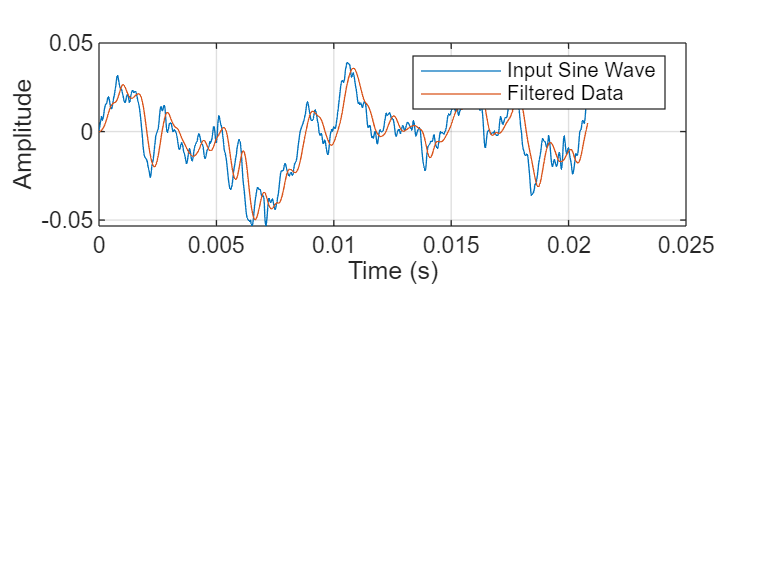

plot(t(1:1000), x(1:1000), t(1:1000), y(1:1000))

xlabel('Time (s)')
ylabel('Amplitude')
legend('Input Sine Wave','Filtered Data')
grid

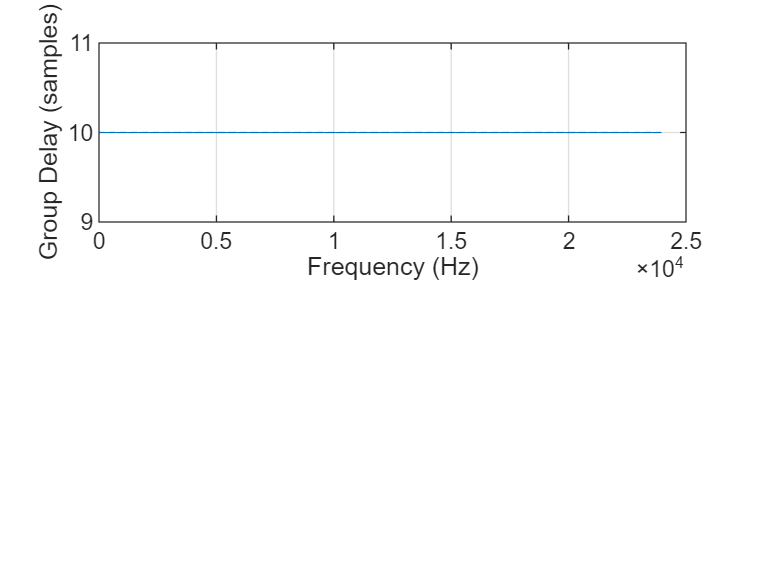

[gd,f] = grpdelay(Hd,[],Fs);

plot(f,gd)
xlabel('Frequency (Hz)')
ylabel('Group Delay (samples)')
grid

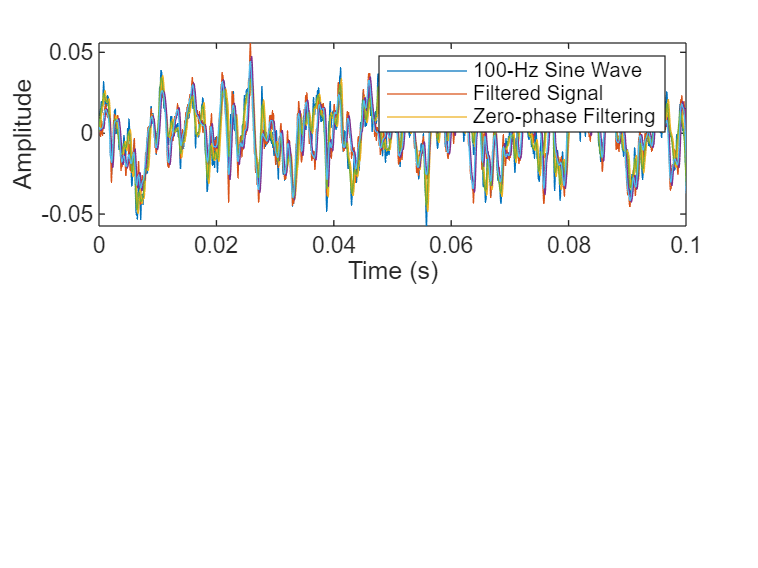

yzp = filtfilt(Hd,x);

plot(t,x,t,y,t,yzp)

sound(yzp, Fs);

xlim([0 0.1])
xlabel('Time (s)')
ylabel('Amplitude')
legend('100-Hz Sine Wave','Filtered Signal','Zero-phase Filtering',...
    'Location','NorthEast')